# Absorption simulation

% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  

init;

**Species**

species = "OH";

*    Add new species in .mat format under ".\LIFSim4.0\input-data\lines\" , *

*    see documentation section "Importing lines and partition function" for details*

**Laser parameters**

unit = '1/cm';
%224.97 - 225.22 ~ 44400 - 44450
startwn = 35540 ;
checkWnum(unit,startwn);
endwn = 35565;
checkWnum(unit,endwn);
step = 0.01;
dnuGL = 0.0001;
dnuLL = 0.00001;

**Environment**

T = 1550;
N = 9.4695998391967;power = 22;
N = N*10^power; fprintf("N = %.2e 1/m^3\n", N);

N = 9.47e+22 1/m^3


L = 0.05;
P = 2;


   *Pressure is only considered if collision model available (NO)*

dnuL = 0.0738652581676698;
dnuSh = 0;

**Collisions data**

colls =  collisions(species);

absWnum = startwn:step:endwn;
plotWnum = absWnum;

if strcmpi(unit,'nm') 
    absWnum = convWnumWlen(absWnum);
    dnuGL = convWnumWlen(dnuGL,endwn);
    dnuLL = convWnumWlen(dnuLL, endwn);
end

[linelist, Z, n, ~,MM] = selectLines(species,absWnum);

if n == 0    
    warning("No lines found.")
    return;
end

if ~isempty(colls)
path = "C:\wangwt\LIFSimProject\LIFSim\input-data\gas-compositions\air+NO.csv";

     *(For Support for NO, otherwise update function 'collissions')*

gas = loadGasComposition(path);

[dnuL, dnuSh] = collisionalBroadening(gas, colls, P, T);
[quen,linelist] = quenchRate(gas, colls, T, P,MM, linelist);
 
end
varargin   = {'Z', Z};

spec = absorptionSpec(absWnum, linelist, MM, T, dnuGL, dnuLL,Z=Z,...
      limit=12, N=N, L=L, dnuL=dnuL, dnuSh=dnuSh, normalize=false);


if strcmpi(unit,'nm') 
    spec = fliplr(spec);
end

### Result plot

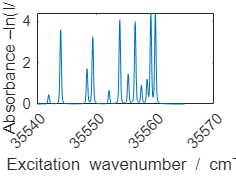

 

figure
plot(plotWnum, spec)

LABELS(unit);
LABELS('abs');